clc; clear; close all;

# Error analysis of 1D-FC using Barycentric Interpolation

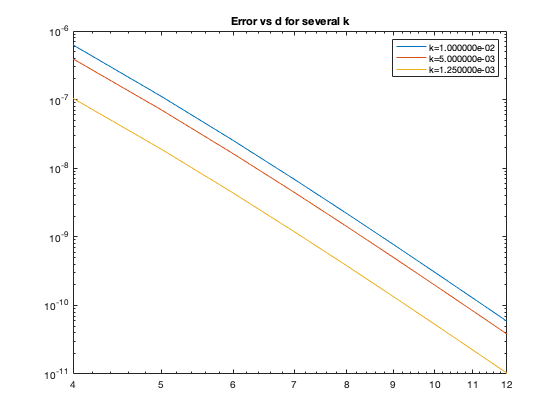

% fixed data
k_lst = [0.01, 0.005, 0.00125];
d_lst = 4:12;
C = 50;
L = 1;

phi = @(x) sin(pi*x/L); % function

% error analysis mesh
k_err = 0.00125/20;
D_err = transpose(0:k_err:L);
phi_D_err = phi(D_err);

% error table
err = zeros(length(k_lst), length(d_lst));

for i = 1:length(k_lst)
    k = k_lst(i);
    D = transpose(0:k:L); % domain
    phi_D = phi(D); % function values on domain

    for j = 1:length(d_lst)
        d = d_lst(j);
        
        D_l = D(1:d); % left side of mesh on domain of function
        D_r = D(end-d+1:end); % right side of mesh on domain of function
        phi_D_l = phi(D_l); % phi values on left side of mesh
        phi_D_r = phi(D_r); % phi values on right side of mesh
        
        D_C = transpose(L+k:k:L+C*k); % vector of only continuation points domain
        D_l_C = D_l + D_C(end) + k; % left side of mesh of next periods domain after continuation, has values of phi_D_l
        
        D_interpolant = [D_r;D_l_C]; % mesh used for interpolation
        phi_interpolant = [phi_D_r; phi_D_l]; % function values used for interpolation
%         w = barycentric_weights([D_r;D_l_C]); % barycentric weights dependent on interpolation mesh
%         phi_C = barycentric_compute_func(w, D_interpolant, phi_interpolant, D_C); % continuation values using barycentric interpolation

        [poly_C, ~, mu] = polyfit(D_interpolant, phi_interpolant, length(D_interpolant)-1);
        phi_C = polyval(poly_C, D_C, [], mu); %matlab interpolation

        
        D_FC = [D; D_C]; % final continued domain
        phi_FC = [phi_D; phi_C]; % final continued function values
        
        % FFT Procedure
        L_FC = D_FC(end) + k; % new period after 1D-FC
        C_n = FFT_coeff(phi_FC); % ceofficients given by FFT
        
        % Error Calculation
        phi_FFT = FFT_compute_func(C_n, L_FC, D_err);
        err(i, j) = max(abs(phi_FFT - phi_D_err));
    end
end

figure;
loglog(d_lst, err)
legend(cellstr(num2str(k_lst', 'k=%-d')));
title("Error vs d for several k");

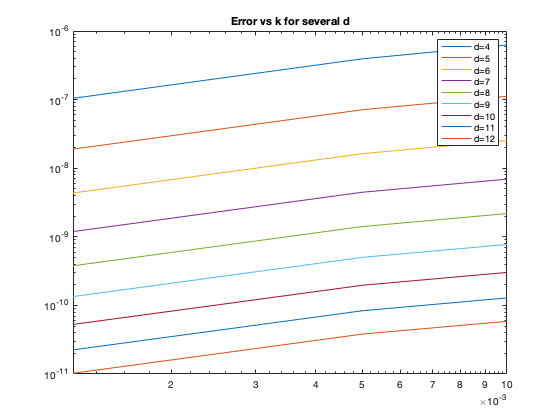


figure;
loglog(k_lst, err)
legend(cellstr(num2str(d_lst', 'd=%-d')));
title("Error vs k for several d");